mmSetFigPublication

Default figure color set to white.
Default font size set to 16.0.

## Read table

T = readtable("CapstoneDatabase.xlsx")

T = 196×10 table
    year     Lstudent_name        Fstudent_name                                                                               project_name                                                                                    chair                 mentor                    x3rdmember              cap_category       deliverable_type        deliverable_SUBtype  
    ____    _______________    ___________________    _____________________________________________________________________________________________________________________________________________________________    ___________________    ___________________    _____________________________    _____________    

T = readtable("ListCapstoneProjects.csv");

T.mentor = categorical(T.mentor);

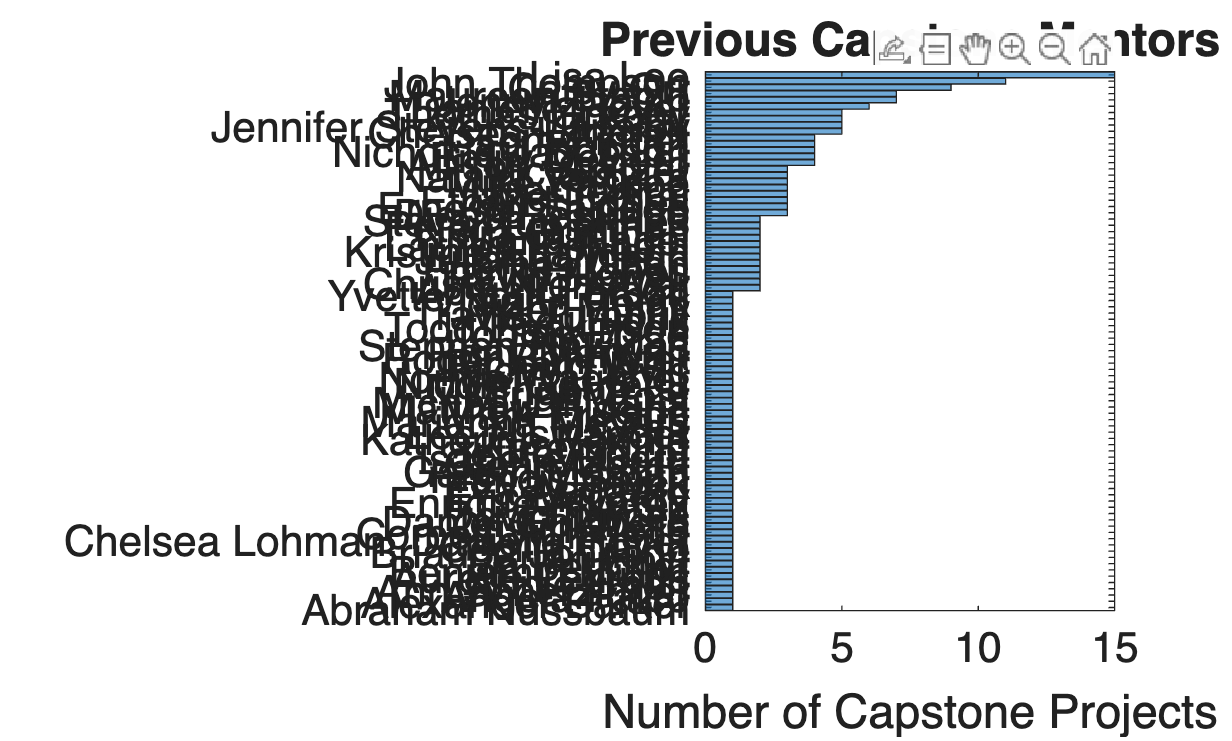

clf;
histogram(T.mentor,Orientation='horizontal',DisplayOrder='ascend')
title("Previous Capstone Mentors")
xlabel('Number of Capstone Projects')

textData = string(T.project_name);
cleanedData = tokenizedDocument(textData);
cleanedData = addPartOfSpeechDetails(cleanedData);
cleanedData = removeStopWords(cleanedData);
cleanedData = normalizeWords(cleanedData,"Style",'lemma');
cleanedData = erasePunctuation(cleanedData);
cleanedData = removeShortWords(cleanedData,2);
cleanedBag = bagOfWords(cleanedData);
cleanedBag = removeInfrequentWords(cleanedBag,2);
cleanedBag=removeEmptyDocuments(cleanedBag)

cleanedBag =   bagOfWords with properties:

        NumWords: 141
          Counts: [176×141 double]
      Vocabulary: ["virtual"    "histology"    "laboratory"    "interactive"    "education"    "segmentation"    "taste"    "cell"    "mouse"    "nerve"    "modeling"    "scan"    "module"    "impact"    "anatomy"    "pathology"    …    ] (1×141 string)
    NumDocuments: 176


figure(Visible="on");
wordcloud(cleanedBag)